%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%% Author: Hyeongmeen Baik, Dheerej
%%%%%%%%%%%% Date: 02/13/2024
%%%%%%%%%%%% Title: ECE 711 - HW2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc
clear
close all
syms theta No Lo



## a)


Ps = sym(2);
Pr = sym(2);

Nsa = (No/Ps)*(cos(Ps/sym(2)*theta));
Nsb = (No/Ps)*(cos(Ps/sym(2)*theta-sym(2*pi/3)));
Nsc = (No/Ps)*(cos(Ps/sym(2)*theta-sym(4*pi/3)));

Nra = (No/Pr)*sign(cos(Pr/sym(2)*theta));
Nrb = (No/Pr)*sign(cos(Pr/sym(2)*theta-sym(2*pi/3)));
Nrc = (No/Pr)*sign(cos(Pr/sym(2)*theta-sym(4*pi/3)));

% No = 1;

% self inductance
Las = Lo*int(Nsa^2,0,2*pi)

$$Las = \frac{\pi \,\mathrm{Lo}\,{\mathrm{No}}^{2}}{4}$$

Lar = Lo*int(Nra^2,0,2*pi)

$$Lar = \frac{\pi \,\mathrm{Lo}\,{\mathrm{No}}^{2}}{2}$$


% fundamental self inductance
as = fund_extract(Nsa,Ps,theta);
Lms = Lo*(int(as^2,0,2*pi))

$$Lms = \frac{\pi \,\mathrm{Lo}\,{\mathrm{No}}^{2}}{4}$$


ar = fund_extract(Nra,Ps,theta);
Lmr = Lo*(int(ar^2,0,2*pi))

$$Lmr = \frac{4\,\mathrm{Lo}\,{\mathrm{No}}^{2}}{\pi }$$


Lls = Las - Lms;
Llr = Lar - Lmr;

% getting estimated values
Lasev = sym(300);
Lmsev = vpa(Lms*Lasev/Las,6)

$$Lmsev = 300.0$$

Llsev = vpa(Lls*Lasev/Las,6)

$$Llsev = 0.0$$

Larev = vpa(Lar*Lasev/Las,6)

$$Larev = 600.0$$

Lmrev = vpa(Lmr*Lasev/Las,6)

$$Lmrev = 486.342$$

Llrev = vpa(Llr*Lasev/Las,6)

$$Llrev = 113.658$$


N_ratio = sqrt(Lmr/Lms)

$$N\_ratio = \frac{4}{\pi }$$

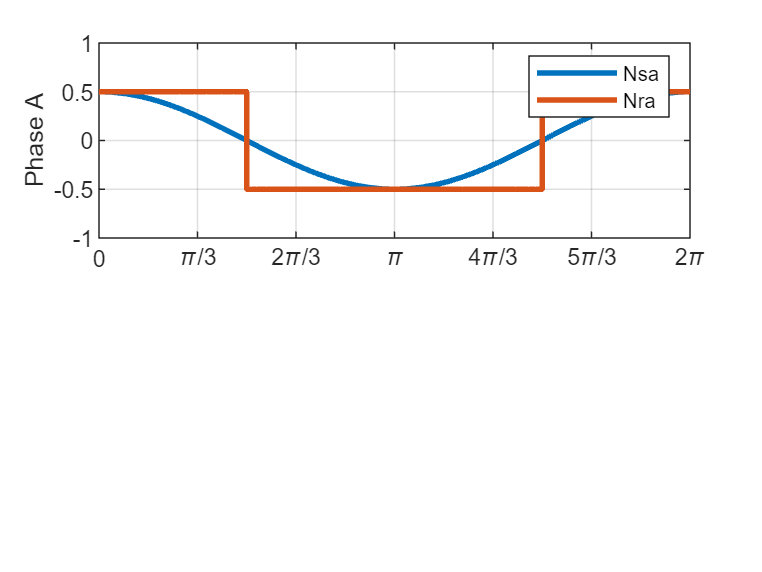


%%
No = 1;
figure(1)
subplot(211);
fplot(subs(Nsa),[0 2*pi],'LineWidth',2,'DisplayName','Nsa')
hold on;grid on;ylabel('Phase A');ylim([-No No]);
fplot(subs(Nra),[0 2*pi],'LineWidth',2,'DisplayName','Nra')
set(gca,'XTick',0:pi/3:2*pi);set(gca,'XTickLabel',{'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi'})
legend

## b)


syms No theta_r t
assume(t,"real")
assume(theta_r,"real")

% for computational issue, assigning theta_r to stator winding function is
% much faster
Nsa = (No/Ps)*(cos(Ps/sym(2)*theta+theta_r));
Nsb = (No/Ps)*(cos(Ps/sym(2)*theta+theta_r-sym(2*pi/3)));
Nsc = (No/Ps)*(cos(Ps/sym(2)*theta+theta_r-sym(4*pi/3)));

Nra = (No/Pr)*sign(cos(Pr/sym(2)*theta));
Nrb = (No/Pr)*sign(cos(Pr/sym(2)*theta-sym(2*pi/3)));
Nrc = (No/Pr)*sign(cos(Pr/sym(2)*theta-sym(4*pi/3)));

% Mutual indutances
Lasbs = Lo*int(Nsa*Nsb,0,2*pi);
Larbr = Lo*int(Nra*Nrb,0,2*pi);
Lasar = Lo*int(Nsa*Nra,0,2*pi);
Lasbr = Lo*int(Nsa*Nrb,0,2*pi);
Lascr = Lo*int(Nsa*Nrb,0,2*pi);
Lar = Lo*int(Nra*Nra,0,2*pi);

% getting estimated values
Lasev = sym(300);
Larev = Lar*Lasev/Las;
Lasbsev = Lasbs*Lasev/Las;
Larbrev = Larbr*Lasev/Las;
Lasarev = Lasar*Lasev/Las;
Lasbrev = Lasbr*Lasev/Las;
Lascrev = Lascr*Lasev/Las;

% set up constraints
w = sym(377);
Im = sym(4);

% Ldi/dt = v
ias = Im*sin(w*t)

$$ias = 4\,\sin\left(377\,t\right)$$

vas = vpa(Lasev/1000*diff(ias,t),6)

$$vas = 452.4\,\cos\left(377.0\,t\right)$$

vbs = vpa(Lasbsev/1000*diff(ias,t),6)

$$vbs = -226.2\,\cos\left(377.0\,t\right)$$

vcs = vpa(Lasbsev/1000*diff(ias,t),6)

$$vcs = -226.2\,\cos\left(377.0\,t\right)$$

var = vpa(Lasarev/1000*diff(ias,t),6)

$$var = 576.014\,\cos\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)$$

vbr = vpa(Lasbrev/1000*diff(ias,t),6)

$$vbr = -576.014\,\cos\left(377.0\,t\right)\,\left(0.5\,\cos\left(\theta_{r}\right)+0.866025\,\sin\left(\theta_{r}\right)\right)$$

vcr = vpa(Lasbrev/1000*diff(ias,t),6)

$$vcr = -576.014\,\cos\left(377.0\,t\right)\,\left(0.5\,\cos\left(\theta_{r}\right)+0.866025\,\sin\left(\theta_{r}\right)\right)$$

## c)


Labcr_s = [Lasarev, Lasbrev, Lasbrev;Lasbrev, Lasarev, Lasbrev;Lasbrev, Lasbrev, Lasarev]/1000

$$Labcr\_s = \begin{array}{l} \left(\begin{array}{ccc} \frac{6\,\cos\left(\theta_{r}\right)}{5\,\pi } & \sigma_{1} & \sigma_{1}\\ \sigma_{1} & \frac{6\,\cos\left(\theta_{r}\right)}{5\,\pi } & \sigma_{1}\\ \sigma_{1} & \sigma_{1} & \frac{6\,\cos\left(\theta_{r}\right)}{5\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{6\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{5\,\pi } \end{array}$$

Labcr_r = [Larev, Larbrev, Larbrev;Larbrev, Larev, Larbrev;Larbrev, Larbrev, Larev]/1000

$$Labcr\_r = \left(\begin{array}{ccc} \frac{3}{5} & -\frac{1}{5} & -\frac{1}{5}\\ -\frac{1}{5} & \frac{3}{5} & -\frac{1}{5}\\ -\frac{1}{5} & -\frac{1}{5} & \frac{3}{5} \end{array}\right)$$

Labcs_s = [Lasev, Lasbsev, Lasbsev;Lasbsev, Lasev, Lasbsev;Lasbsev, Lasbsev, Lasev]/1000

$$Labcs\_s = \left(\begin{array}{ccc} \frac{3}{10} & -\frac{3}{20} & -\frac{3}{20}\\ -\frac{3}{20} & \frac{3}{10} & -\frac{3}{20}\\ -\frac{3}{20} & -\frac{3}{20} & \frac{3}{10} \end{array}\right)$$

Labcs_r = [Lasarev, Lasbrev, Lasbrev;Lasbrev, Lasarev, Lasbrev;Lasbrev, Lasbrev, Lasarev]/1000

$$Labcs\_r = \begin{array}{l} \left(\begin{array}{ccc} \frac{6\,\cos\left(\theta_{r}\right)}{5\,\pi } & \sigma_{1} & \sigma_{1}\\ \sigma_{1} & \frac{6\,\cos\left(\theta_{r}\right)}{5\,\pi } & \sigma_{1}\\ \sigma_{1} & \sigma_{1} & \frac{6\,\cos\left(\theta_{r}\right)}{5\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{6\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{5\,\pi } \end{array}$$


% lambda abcr should be zero
% iabcr = - inv(Labcr_r)*Labcr_s*iabcs

iabcs = [ias;0;0]

$$iabcs = \left(\begin{array}{c} 4\,\sin\left(377\,t\right)\\ 0\\ 0 \end{array}\right)$$

iabcr = -inv(Labcr_r)*Labcr_s*iabcs

$$iabcr = \begin{array}{l} \left(\begin{array}{c} 4\,\sin\left(377\,t\right)\,\left(\frac{3\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,\sin\left(377\,t\right)\,\left(\frac{9\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi }\right) \end{array}$$

iar = vpa(iabcr(1,1),6)

$$iar = -4.0\,\sin\left(377.0\,t\right)\,\left(0.477465\,\cos\left(\theta_{r}\right)-0.826993\,\sin\left(\theta_{r}\right)\right)$$

ibr = vpa(iabcr(2,1),6)

$$ibr = 4.0\,\sin\left(377.0\,t\right)\,\left(0.238732\,\cos\left(\theta_{r}\right)+1.24049\,\sin\left(\theta_{r}\right)\right)$$

icr = vpa(iabcr(3,1),6)

$$icr = 4.0\,\sin\left(377.0\,t\right)\,\left(0.238732\,\cos\left(\theta_{r}\right)+1.24049\,\sin\left(\theta_{r}\right)\right)$$


Lambda_abcs_r = Labcs_r*iabcr

$$Lambda\_abcs\_r = \begin{array}{l} \left(\begin{array}{c} \frac{24\,\sin\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\left(\frac{3\,\sigma_{3}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)}{5\,\pi }-\frac{48\,\sin\left(377\,t\right)\,\sigma_{3}\,\sigma_{2}}{5\,\pi }\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{24\,\sin\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\sigma_{2}}{5\,\pi }-\frac{24\,\sin\left(377\,t\right)\,\sigma_{3}\,\sigma_{2}}{5\,\pi }-\frac{24\,\sin\left(377\,t\right)\,\sigma_{3}\,\left(\frac{3\,\sigma_{3}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)}{5\,\pi }\\ \sigma_{2}=\frac{9\,\sigma_{3}}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi }\\ \sigma_{3}=\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2} \end{array}$$

Lambda_abcs_s = Labcs_s*iabcs

$$Lambda\_abcs\_s = \left(\begin{array}{c} \frac{6\,\sin\left(377\,t\right)}{5}\\ -\frac{3\,\sin\left(377\,t\right)}{5}\\ -\frac{3\,\sin\left(377\,t\right)}{5} \end{array}\right)$$

Lambda_abcs = Lambda_abcs_s + Lambda_abcs_r

$$Lambda\_abcs = \begin{array}{l} \left(\begin{array}{c} \frac{6\,\sin\left(377\,t\right)}{5}-\frac{48\,\sin\left(377\,t\right)\,\sigma_{3}\,\sigma_{2}}{5\,\pi }+\frac{24\,\sin\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\left(\frac{3\,\sigma_{3}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)}{5\,\pi }\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{24\,\sin\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\sigma_{2}}{5\,\pi }-\frac{24\,\sin\left(377\,t\right)\,\sigma_{3}\,\left(\frac{3\,\sigma_{3}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)}{5\,\pi }-\frac{24\,\sin\left(377\,t\right)\,\sigma_{3}\,\sigma_{2}}{5\,\pi }-\frac{3\,\sin\left(377\,t\right)}{5}\\ \sigma_{2}=\frac{9\,\sigma_{3}}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi }\\ \sigma_{3}=\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2} \end{array}$$


Lambdaabcs = diff(Lambda_abcs,t)

$$Lambdaabcs = \begin{array}{l} \left(\begin{array}{c} \frac{2262\,\cos\left(377\,t\right)}{5}-\frac{18096\,\cos\left(377\,t\right)\,\sigma_{3}\,\sigma_{2}}{5\,\pi }+\frac{9048\,\cos\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\left(\frac{3\,\sigma_{3}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)}{5\,\pi }\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{9048\,\cos\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\sigma_{2}}{5\,\pi }-\frac{9048\,\cos\left(377\,t\right)\,\sigma_{3}\,\left(\frac{3\,\sigma_{3}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)}{5\,\pi }-\frac{9048\,\cos\left(377\,t\right)\,\sigma_{3}\,\sigma_{2}}{5\,\pi }-\frac{1131\,\cos\left(377\,t\right)}{5}\\ \sigma_{2}=\frac{9\,\sigma_{3}}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi }\\ \sigma_{3}=\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2} \end{array}$$

vas = simplify(Lambdaabcs(1,1),6)

$$vas = \frac{2262\,\cos\left(377\,t\right)\,\left(6\,\sqrt{3}\,\cos\left(2\,\theta_{r}+\frac{\pi }{6}\right)+\pi^{2}-18\right)}{5\,\pi^{2}}$$

vbs = simplify(Lambdaabcs(2,1),6)

$$vbs = \frac{1131\,\cos\left(377\,t\right)\,\left(27\,\cos\left(2\,\theta_{r}\right)+3\,\sqrt{3}\,\sin\left(2\,\theta_{r}\right)-\pi^{2}-18\right)}{5\,\pi^{2}}$$

vcs = simplify(Lambdaabcs(3,1),6)

$$vcs = \frac{1131\,\cos\left(377\,t\right)\,\left(27\,\cos\left(2\,\theta_{r}\right)+3\,\sqrt{3}\,\sin\left(2\,\theta_{r}\right)-\pi^{2}-18\right)}{5\,\pi^{2}}$$

% vas = Las*dias/dt + Nr/Ns*Lms*[d(iar*cos(theta_r))/dt 


## d) and e)


ias = Im*sin(w*t)

$$ias = 4\,\sin\left(377\,t\right)$$

ibs = Im*sin(w*t-2*sym(pi)/3)

$$ibs = 4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)$$

ics = Im*sin(w*t-4*sym(pi)/3)

$$ics = 4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)$$

a = exp(j*2*pi/3)

a = -0.5000 + 0.8660i

Iabcs = simplify(2/3*(ias+a*ibs+a^2*ics))

$$Iabcs = 4\,\sin\left(377\,t\right)-4\,\cos\left(377\,t\right)\,\mathrm{i}$$

Lambdaabcs = simplify((Lasev - Lasbsev)*Iabcs)/1000

$$Lambdaabcs = \frac{9\,\sin\left(377\,t\right)}{5}-\frac{9\,\cos\left(377\,t\right)\,\mathrm{i}}{5}$$

Lambdabcr = expand((Lasarev - Lasbrev)*Iabcs/1000,'ArithmeticOnly',true)

$$Lambdabcr = \frac{36\,\sin\left(377\,t\right)\,\cos\left(\theta_{r}\right)}{5\,\pi }+\frac{12\,\sqrt{3}\,\sin\left(377\,t\right)\,\sin\left(\theta_{r}\right)}{5\,\pi }-\frac{36\,\cos\left(377\,t\right)\,\cos\left(\theta_{r}\right)\,\mathrm{i}}{5\,\pi }-\frac{12\,\sqrt{3}\,\cos\left(377\,t\right)\,\sin\left(\theta_{r}\right)\,\mathrm{i}}{5\,\pi }$$

vabcs = diff(Lambdaabcs,t)

$$vabcs = \frac{3393\,\cos\left(377\,t\right)}{5}+\frac{3393\,\sin\left(377\,t\right)\,\mathrm{i}}{5}$$

vabcr = vpa(diff(Lambdabcr,t),4)

$$vabcr = 864.0\,\cos\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)+498.8\,\cos\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)+864.0\,\sin\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)\,\mathrm{i}+498.8\,\sin\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)\,\mathrm{i}$$

vas = vpa(real(vabcs),4)

$$vas = 678.6\,\cos\left(377.0\,t\right)$$

vas_check = vpa(real(vabcs),4)

$$vas\_check = 678.6\,\cos\left(377.0\,t\right)$$

vbs = vpa(real(vabcs*a^2),4)

$$vbs = 587.7\,\sin\left(377.0\,t\right)-339.3\,\cos\left(377.0\,t\right)$$

vcs = vpa(real(vabcs*a),4)

$$vcs = -339.3\,\cos\left(377.0\,t\right)-587.7\,\sin\left(377.0\,t\right)$$


var = vpa(real(vabcr),4)

$$var = 864.0\,\cos\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)+498.8\,\cos\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)$$

vbr = vpa(real(vabcr*a^2),4)

$$vbr = 748.3\,\sin\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)-249.4\,\cos\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)-432.0\,\cos\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)+432.0\,\sin\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)$$

vcr = vpa(real(vabcr*a),4)

$$vcr = -432.0\,\cos\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)-249.4\,\cos\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)-748.3\,\sin\left(377.0\,t\right)\,\cos\left(\theta_{r}\right)-432.0\,\sin\left(377.0\,t\right)\,\sin\left(\theta_{r}\right)$$

## f)



iabcs = [ias;ibs;ics]

$$iabcs = \left(\begin{array}{c} 4\,\sin\left(377\,t\right)\\ 4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\\ 4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right) \end{array}\right)$$

iabcr = -inv(Labcr_r)*Labcr_s*iabcs

$$iabcr = \begin{array}{l} \left(\begin{array}{c} 4\,\sin\left(377\,t\right)\,\sigma_{1}+\sigma_{3}+\sigma_{2}\\ 4\,\sin\left(377\,t\right)\,\sigma_{4}+4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\,\sigma_{1}+\sigma_{2}\\ 4\,\sin\left(377\,t\right)\,\sigma_{4}+4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)\,\sigma_{1}+\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sigma_{5}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\\ \sigma_{2}=4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)\,\sigma_{4}\\ \sigma_{3}=4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\,\sigma_{4}\\ \sigma_{4}=\frac{9\,\sigma_{5}}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi }\\ \sigma_{5}=\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2} \end{array}$$



iar = iabcr(1,1)

$$iar = \begin{array}{l} 4\,\sin\left(377\,t\right)\,\left(\frac{3\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)+4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\,\sigma_{1}+4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{9\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi } \end{array}$$

ibr = iabcr(2,1)

$$ibr = \begin{array}{l} 4\,\sin\left(377\,t\right)\,\sigma_{1}+4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\,\left(\frac{3\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)+4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{9\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi } \end{array}$$

icr = iabcr(3,1)

$$icr = \begin{array}{l} 4\,\sin\left(377\,t\right)\,\sigma_{1}+4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)\,\left(\frac{3\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\right)+4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{9\,\left(\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2}\right)}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi } \end{array}$$

i0r = simplify(iar+ibr+icr)

$$i0r = 0$$


Lambda_abcs_r = Labcs_r*iabcr;
Lambda_abcs_s = Labcs_s*iabcs;
Lambda_abcs = Lambda_abcs_s + Lambda_abcs_r

$$Lambda\_abcs = \begin{array}{l} \left(\begin{array}{c} \frac{6\,\sin\left(377\,t\right)}{5}-\frac{3\,\sigma_{11}}{5}-\frac{3\,\sigma_{10}}{5}+\frac{6\,\cos\left(\theta_{r}\right)\,\sigma_{7}}{5\,\pi }-\sigma_{3}-\sigma_{2}\\ \frac{6\,\sigma_{11}}{5}-\sigma_{1}-\frac{3\,\sigma_{10}}{5}+\frac{6\,\cos\left(\theta_{r}\right)\,\sigma_{6}}{5\,\pi }-\sigma_{4}-\sigma_{2}\\ \frac{6\,\sigma_{10}}{5}-\frac{3\,\sigma_{11}}{5}-\sigma_{1}+\frac{6\,\cos\left(\theta_{r}\right)\,\sigma_{5}}{5\,\pi }-\sigma_{4}-\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sin\left(377\,t\right)}{5}\\ \sigma_{2}=\frac{6\,\sigma_{13}\,\sigma_{5}}{5\,\pi }\\ \sigma_{3}=\frac{6\,\sigma_{13}\,\sigma_{6}}{5\,\pi }\\ \sigma_{4}=\frac{6\,\sigma_{13}\,\sigma_{7}}{5\,\pi }\\ \sigma_{5}=\sigma_{8}+4\,\sigma_{10}\,\sigma_{9}+4\,\sigma_{11}\,\sigma_{12}\\ \sigma_{6}=\sigma_{8}+4\,\sigma_{11}\,\sigma_{9}+4\,\sigma_{10}\,\sigma_{12}\\ \sigma_{7}=4\,\sin\left(377\,t\right)\,\sigma_{9}+4\,\sigma_{11}\,\sigma_{12}+4\,\sigma_{10}\,\sigma_{12}\\ \sigma_{8}=4\,\sin\left(377\,t\right)\,\sigma_{12}\\ \sigma_{9}=\frac{3\,\sigma_{13}}{\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{\pi }\\ \sigma_{10}=\sin\left(377\,t-\frac{4\,\pi }{3}\right)\\ \sigma_{11}=\sin\left(377\,t-\frac{2\,\pi }{3}\right)\\ \sigma_{12}=\frac{9\,\sigma_{13}}{2\,\pi }-\frac{3\,\cos\left(\theta_{r}\right)}{2\,\pi }\\ \sigma_{13}=\frac{\cos\left(\theta_{r}\right)}{2}+\frac{\sqrt{3}\,\sin\left(\theta_{r}\right)}{2} \end{array}$$


Lambdaabcs = Lambda_abcs;
vabcs = diff(Lambdaabcs,t);
vas = simplify(vabcs(1,1))

$$vas = -\frac{3393\,\cos\left(377\,t\right)\,\left(6\,\cos\left(2\,\theta_{r}-\frac{\pi }{3}\right)-\pi^{2}+6\right)}{5\,\pi^{2}}$$

vbs = simplify(vabcs(2,1))

$$vbs = \begin{array}{l} -\frac{10179\,\cos\left(\sigma_{1}\right)-20358\,\cos\left(377\,t\right)-20358\,\cos\left(377\,t+2\,\theta_{r}\right)+20358\,\sqrt{3}\,\sin\left(377\,t\right)+10179\,\sqrt{3}\,\sin\left(\sigma_{1}\right)+3393\,\pi^{2}\,\cos\left(377\,t\right)-3393\,\sqrt{3}\,\pi^{2}\,\sin\left(377\,t\right)}{10\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=377\,t-2\,\theta_{r} \end{array}$$

vcs = simplify(vabcs(3,1))

$$vcs = \begin{array}{l} \frac{20358\,\cos\left(377\,t\right)+20358\,\cos\left(377\,t-2\,\theta_{r}\right)-10179\,\cos\left(\sigma_{1}\right)+20358\,\sqrt{3}\,\sin\left(377\,t\right)+10179\,\sqrt{3}\,\sin\left(\sigma_{1}\right)-3393\,\pi^{2}\,\cos\left(377\,t\right)-3393\,\sqrt{3}\,\pi^{2}\,\sin\left(377\,t\right)}{10\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=377\,t+2\,\theta_{r} \end{array}$$


vabcs = simplify(2/3*(vas+vbs*a+vcs*a))

$$vabcs = -\frac{1131\,\cos\left(377\,t\right)\,\left(9\,\cos\left(2\,\theta_{r}\right)+9\,\sqrt{3}\,\sin\left(2\,\theta_{r}\right)-3\,\pi^{2}+18-9\,\sin\left(2\,\theta_{r}\right)\,\mathrm{i}-6\,\sqrt{3}\,\mathrm{i}+\sqrt{3}\,\pi^{2}\,\mathrm{i}-3\,\sqrt{3}\,\cos\left(2\,\theta_{r}\right)\,\mathrm{i}\right)}{5\,\pi^{2}}$$

iabcr = simplify(2/3*(iar+ibr*a+icr*a))

$$iabcr = -\frac{3\,\sin\left(377\,t\right)\,\left(3\,\cos\left(\theta_{r}\right)+\sqrt{3}\,\sin\left(\theta_{r}\right)-\sin\left(\theta_{r}\right)\,\mathrm{i}-\sqrt{3}\,\cos\left(\theta_{r}\right)\,\mathrm{i}\right)}{\pi }$$


vas_recovered = real(vabcs)

$$vas\_recovered = -\frac{1131\,\cos\left(377\,t\right)\,\left(9\,\cos\left(2\,\theta_{r}\right)+9\,\sqrt{3}\,\sin\left(2\,\theta_{r}\right)-3\,\pi^{2}+18\right)}{5\,\pi^{2}}$$

err = simplify(vas-vas_recovered)

$$err = 0$$


%% Appendix
% verification between matrix method and complex vector method (e)
ias = Im*sin(w*t)

$$ias = 4\,\sin\left(377\,t\right)$$

ibs = Im*sin(w*t-2*sym(pi)/3)

$$ibs = 4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)$$

ics = Im*sin(w*t-4*sym(pi)/3)

$$ics = 4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)$$

iabcs = [ias;ibs;ics]

$$iabcs = \left(\begin{array}{c} 4\,\sin\left(377\,t\right)\\ 4\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)\\ 4\,\sin\left(377\,t-\frac{4\,\pi }{3}\right) \end{array}\right)$$

Lambda_abcs_s = Labcs_s*iabcs

$$Lambda\_abcs\_s = \begin{array}{l} \left(\begin{array}{c} \frac{6\,\sin\left(377\,t\right)}{5}-\sigma_{2}-\sigma_{1}\\ \frac{6\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)}{5}-\frac{3\,\sin\left(377\,t\right)}{5}-\sigma_{1}\\ \frac{6\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)}{5}-\sigma_{2}-\frac{3\,\sin\left(377\,t\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)}{5}\\ \sigma_{2}=\frac{3\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)}{5} \end{array}$$

Lambda_abcs = Lambda_abcs_s

$$Lambda\_abcs = \begin{array}{l} \left(\begin{array}{c} \frac{6\,\sin\left(377\,t\right)}{5}-\sigma_{2}-\sigma_{1}\\ \frac{6\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)}{5}-\frac{3\,\sin\left(377\,t\right)}{5}-\sigma_{1}\\ \frac{6\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)}{5}-\sigma_{2}-\frac{3\,\sin\left(377\,t\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sin\left(377\,t-\frac{4\,\pi }{3}\right)}{5}\\ \sigma_{2}=\frac{3\,\sin\left(377\,t-\frac{2\,\pi }{3}\right)}{5} \end{array}$$

Lambdaabcs = diff(Lambda_abcs,t)

$$Lambdaabcs = \begin{array}{l} \left(\begin{array}{c} \frac{2262\,\cos\left(377\,t\right)}{5}-\sigma_{2}-\sigma_{1}\\ \frac{2262\,\cos\left(377\,t-\frac{2\,\pi }{3}\right)}{5}-\frac{1131\,\cos\left(377\,t\right)}{5}-\sigma_{1}\\ \frac{2262\,\cos\left(377\,t-\frac{4\,\pi }{3}\right)}{5}-\sigma_{2}-\frac{1131\,\cos\left(377\,t\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1131\,\cos\left(377\,t-\frac{4\,\pi }{3}\right)}{5}\\ \sigma_{2}=\frac{1131\,\cos\left(377\,t-\frac{2\,\pi }{3}\right)}{5} \end{array}$$

vas_temp = vpa(Lambdaabcs(1,1),6)

$$vas\_temp = 452.4\,\cos\left(377.0\,t\right)-226.2\,\cos\left(377.0\,t-4.18879\right)-226.2\,\cos\left(377.0\,t-2.0944\right)$$

vbs = vpa(Lambdaabcs(2,1),6)

$$vbs = 452.4\,\cos\left(377.0\,t-2.0944\right)-226.2\,\cos\left(377.0\,t-4.18879\right)-226.2\,\cos\left(377.0\,t\right)$$

vcs = vpa(Lambdaabcs(3,1),6)

$$vcs = 452.4\,\cos\left(377.0\,t-4.18879\right)-226.2\,\cos\left(377.0\,t-2.0944\right)-226.2\,\cos\left(377.0\,t\right)$$


theta_r = 0

theta_r = 0

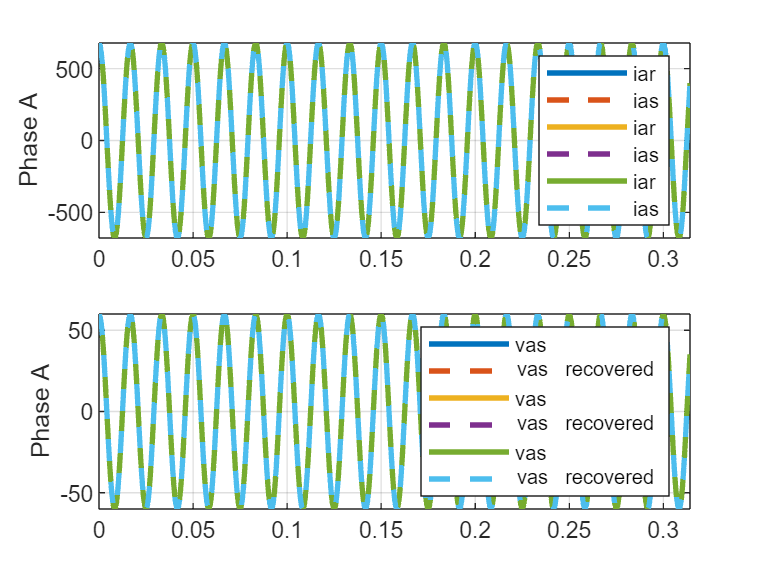

No = 1;
figure(3)
subplot(211);
fplot(subs(vas_check),[0 pi/10],'LineWidth',2,'DisplayName','iar')
hold on;grid on;ylabel('Phase A');
fplot(subs(vas_temp),[0 pi/10],'--','LineWidth',2,'DisplayName','ias')
% set(gca,'XTick',0:pi/3:2*pi);set(gca,'XTickLabel',{'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi'})
legend

% recovered signal from f)
subplot(212);
fplot(subs(vas),[0 pi/10],'LineWidth',2,'DisplayName','vas')
hold on;grid on;ylabel('Phase A');
fplot(subs(vas_recovered),[0 pi/10],'--','LineWidth',2,'DisplayName','vas _ recovered')

% set(gca,'XTick',0:pi/3:2*pi);set(gca,'XTickLabel',{'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi'})
legend
%% functions
% fundamental

function out = fund_extract(Nsa,Ps,theta)
    % fundamental self inductance
    C_pos1 = 1/2/sym(pi)*int(Nsa*exp(-j*theta*2/Ps),0,2*pi);
    C_neg1 = 1/2/sym(pi)*int(Nsa*exp(j*theta*2/Ps),0,2*pi);
    k = sqrt((C_pos1+C_neg1)^2+(j*C_pos1-j*C_neg1)^2);
    if C_neg1+C_pos1 ==0
        if subs(j*(C_pos1-C_neg1),No,1)>0
            phi = pi/2;
        else 
            phi = -pi/2;
        end
    else
        phi = atan(j*((C_pos1-C_neg1)/(C_neg1+C_pos1))); %%% phi = -pi/2
    end
    out = k*sin(theta+phi);
end